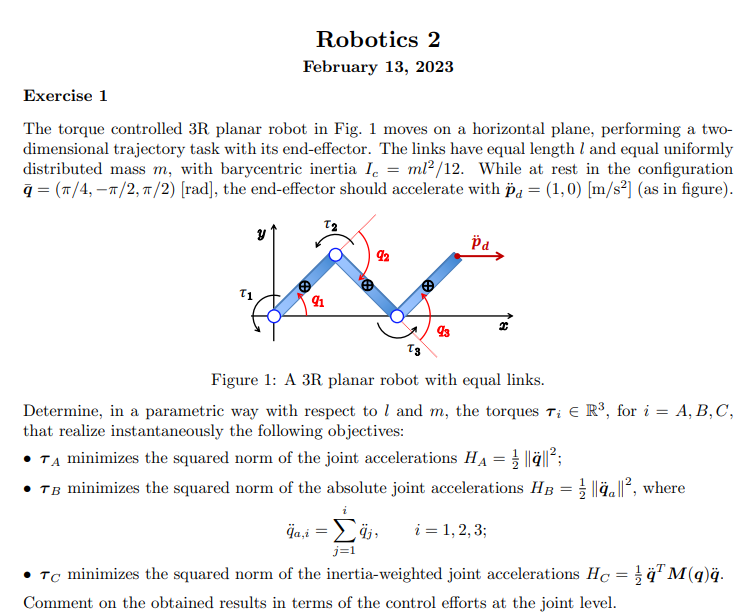

syms q1 q2 q3 q_dot_1 q_dot_2 q_dot_3 L m real

x1 = L/2*cos(q1);
y1 = L/2*sin(q1);

vx1 = diff(x1,q1)*q_dot_1 + diff(x1,q2)*q_dot_2 + diff(x1,q3)*q_dot_3

$$vx1 = -\frac{L\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)}{2}$$

vy1 = diff(y1,q1)*q_dot_1 + diff(y1,q2)*q_dot_2 + diff(y1,q3)*q_dot_3

$$vy1 = \frac{L\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)}{2}$$


T1 = 0.5*m*[vx1 vy1]*[vx1; vy1;] + 0.5*(q_dot_1^2)*((1/12)*m*L^2)

$$T1 = \frac{m\,L^{2}\,{{\dot{q}}_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{8}+\frac{m\,L^{2}\,{{\dot{q}}_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}}{8}+\frac{m\,L^{2}\,{{\dot{q}}_{1}}^{2}}{24}$$


x2 = L*cos(q1) + L/2*cos(q1+q2);
y2 = L*sin(q1) + L/2*sin(q1+q2);

vx2 = diff(x2,q1)*q_dot_1 + diff(x2,q2)*q_dot_2 + diff(x2,q3)*q_dot_3

$$vx2 = -{\dot{q}}_{1}\,\left(\frac{L\,\sin\left(q_{1}+q_{2}\right)}{2}+L\,\sin\left(q_{1}\right)\right)-\frac{L\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}$$

vy2 = diff(y2,q1)*q_dot_1 + diff(y2,q2)*q_dot_2 + diff(y2,q3)*q_dot_3

$$vy2 = {\dot{q}}_{1}\,\left(\frac{L\,\cos\left(q_{1}+q_{2}\right)}{2}+L\,\cos\left(q_{1}\right)\right)+\frac{L\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}$$


T2 = 0.5*m*[vx2 vy2]*[vx2; vy2;] + 0.5*((q_dot_1+q_dot_2)^2)*((1/12)*m*L^2)

$$T2 = \frac{m\,{\left({\dot{q}}_{1}\,\left(\frac{L\,\cos\left(q_{1}+q_{2}\right)}{2}+L\,\cos\left(q_{1}\right)\right)+\frac{L\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}\right)}^{2}}{2}+\frac{m\,{\left({\dot{q}}_{1}\,\left(\frac{L\,\sin\left(q_{1}+q_{2}\right)}{2}+L\,\sin\left(q_{1}\right)\right)+\frac{L\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}\right)}^{2}}{2}+\frac{L^{2}\,m\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{24}$$


x3 = L*cos(q1) + L*cos(q1+q2) + L/2*cos(q1+q2+q3);
y3 = L*sin(q1) + L*sin(q1+q2) + L/2*sin(q1+q2+q3);

vx3 = diff(x3,q1)*q_dot_1 + diff(x3,q2)*q_dot_2 + diff(x3,q3)*q_dot_3

$$vx3 = -{\dot{q}}_{2}\,\left(L\,\sin\left(q_{1}+q_{2}\right)+\frac{L\,\sin\left(q_{1}+q_{2}+q_{3}\right)}{2}\right)-{\dot{q}}_{1}\,\left(L\,\sin\left(q_{1}+q_{2}\right)+L\,\sin\left(q_{1}\right)+\frac{L\,\sin\left(q_{1}+q_{2}+q_{3}\right)}{2}\right)-\frac{L\,{\dot{q}}_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)}{2}$$

vy3 = diff(y3,q1)*q_dot_1 + diff(y3,q2)*q_dot_2 + diff(y3,q3)*q_dot_3

$$vy3 = {\dot{q}}_{2}\,\left(L\,\cos\left(q_{1}+q_{2}\right)+\frac{L\,\cos\left(q_{1}+q_{2}+q_{3}\right)}{2}\right)+{\dot{q}}_{1}\,\left(L\,\cos\left(q_{1}+q_{2}\right)+L\,\cos\left(q_{1}\right)+\frac{L\,\cos\left(q_{1}+q_{2}+q_{3}\right)}{2}\right)+\frac{L\,{\dot{q}}_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)}{2}$$


T3 = 0.5*m*[vx3 vy3]*[vx3; vy3;] + 0.5*((q_dot_1+q_dot_2+q_dot_3)^2)*((1/12)*m*L^2)

$$T3 = \begin{array}{l} \frac{m\,{\left({\dot{q}}_{2}\,\left(\sigma_{1}+\frac{L\,\sigma_{3}}{2}\right)+{\dot{q}}_{1}\,\left(\sigma_{1}+L\,\sin\left(q_{1}\right)+\frac{L\,\sigma_{3}}{2}\right)+\frac{L\,{\dot{q}}_{3}\,\sigma_{3}}{2}\right)}^{2}}{2}+\frac{m\,{\left({\dot{q}}_{2}\,\left(\sigma_{2}+\frac{L\,\sigma_{4}}{2}\right)+{\dot{q}}_{1}\,\left(\sigma_{2}+L\,\cos\left(q_{1}\right)+\frac{L\,\sigma_{4}}{2}\right)+\frac{L\,{\dot{q}}_{3}\,\sigma_{4}}{2}\right)}^{2}}{2}+\frac{L^{2}\,m\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{24}\\ \mathrm{where}\\ \sigma_{1}=L\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{2}=L\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{3}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$


T = T1+T2+T3

$$T = \begin{array}{l} \frac{m\,{\left({\dot{q}}_{2}\,\left(\sigma_{1}+\frac{L\,\sigma_{3}}{2}\right)+{\dot{q}}_{1}\,\left(\sigma_{1}+L\,\sin\left(q_{1}\right)+\frac{L\,\sigma_{3}}{2}\right)+\frac{L\,{\dot{q}}_{3}\,\sigma_{3}}{2}\right)}^{2}}{2}+\frac{m\,{\left({\dot{q}}_{1}\,\left(\frac{\sigma_{2}}{2}+L\,\cos\left(q_{1}\right)\right)+\frac{L\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}\right)}^{2}}{2}+\frac{m\,{\left({\dot{q}}_{1}\,\left(\frac{\sigma_{1}}{2}+L\,\sin\left(q_{1}\right)\right)+\frac{L\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}\right)}^{2}}{2}+\frac{m\,{\left({\dot{q}}_{2}\,\left(\sigma_{2}+\frac{L\,\sigma_{4}}{2}\right)+{\dot{q}}_{1}\,\left(\sigma_{2}+L\,\cos\left(q_{1}\right)+\frac{L\,\sigma_{4}}{2}\right)+\frac{L\,{\dot{q}}_{3}\,\sigma_{4}}{2}\right)}^{2}}{2}+\frac{L^{2}\,m\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{24}+\frac{L^{2}\,m\,{{\dot{q}}_{1}}^{2}}{24}+\frac{L^{2}\,m\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{24}+\frac{L^{2}\,m\,{{\dot{q}}_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{8}+\frac{L^{2}\,m\,{{\dot{q}}_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}}{8}\\ \mathrm{where}\\ \sigma_{1}=L\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{2}=L\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{3}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);
M13 = diff(diff(T, q_dot_1), q_dot_3);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);
M23 = diff(diff(T, q_dot_2), q_dot_3);

M31 = diff(diff(T, q_dot_3), q_dot_1);
M32 = diff(diff(T, q_dot_3), q_dot_2);
M33 = diff(diff(T, q_dot_3), q_dot_3);

M = simplify([M11, M12, M13; M21, M22, M23; M31, M32, M33])

$$M = \begin{array}{l} \left(\begin{array}{ccc} L^{2}\,m\,\left(\cos\left(q_{2}+q_{3}\right)+3\,\cos\left(q_{2}\right)+\cos\left(q_{3}\right)+4\right) & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & \frac{L^{2}\,m\,\left(3\,\cos\left(q_{3}\right)+5\right)}{3} & \frac{L^{2}\,m\,\left(3\,\cos\left(q_{3}\right)+2\right)}{6}\\ \sigma_{2} & \frac{L^{2}\,m\,\left(3\,\cos\left(q_{3}\right)+2\right)}{6} & \frac{L^{2}\,m}{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{L^{2}\,m\,\left(3\,\cos\left(q_{2}+q_{3}\right)+9\,\cos\left(q_{2}\right)+6\,\cos\left(q_{3}\right)+10\right)}{6}\\ \sigma_{2}=\frac{L^{2}\,m\,\left(3\,\cos\left(q_{2}+q_{3}\right)+3\,\cos\left(q_{3}\right)+2\right)}{6} \end{array}$$

M_subs = eval(subs(M,[q1,q2,q3],[pi/4, -pi/2, pi/2]))

$$M\_subs = \left(\begin{array}{ccc} 5\,L^{2}\,m & \frac{13\,L^{2}\,m}{6} & \frac{5\,L^{2}\,m}{6}\\ \frac{13\,L^{2}\,m}{6} & \frac{5\,L^{2}\,m}{3} & \frac{L^{2}\,m}{3}\\ \frac{5\,L^{2}\,m}{6} & \frac{L^{2}\,m}{3} & \frac{L^{2}\,m}{3} \end{array}\right)$$

M_subs_inv = inv(M_subs)

$$M\_subs\_inv = \begin{array}{l} \left(\begin{array}{ccc} \frac{12}{19\,L^{2}\,m} & -\frac{12}{19\,L^{2}\,m} & -\frac{18}{19\,L^{2}\,m}\\ -\frac{12}{19\,L^{2}\,m} & \frac{105}{\sigma_{1}} & \frac{15}{\sigma_{1}}\\ -\frac{18}{19\,L^{2}\,m} & \frac{15}{\sigma_{1}} & \frac{393}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=76\,L^{2}\,m \end{array}$$


% Coriolis and Centrifugal terms
q  = [q1; q2; q3;];
dq = [q_dot_1; q_dot_2; q_dot_3;];
C = sym(zeros(3,3));

for i = 1:3
    for j = 1:3
        tmp = 0;
        for k = 1:3
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\begin{array}{l} \left(\begin{array}{ccc} -\frac{L^{2}\,m\,{\dot{q}}_{2}\,\left(\sin\left(q_{2}+q_{3}\right)+3\,\sin\left(q_{2}\right)\right)}{2}-\frac{L^{2}\,m\,{\dot{q}}_{3}\,\sigma_{2}}{2} & -\frac{L^{2}\,m\,\left(\sigma_{1}+{\dot{q}}_{2}\,\sin\left(q_{2}+q_{3}\right)+{\dot{q}}_{3}\,\sin\left(q_{2}+q_{3}\right)+\sigma_{3}+3\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)+{\dot{q}}_{3}\,\sin\left(q_{3}\right)\right)}{2} & -\frac{L^{2}\,m\,\sigma_{2}\,\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}{2}\\ \frac{L^{2}\,m\,\left(\sigma_{1}+\sigma_{3}-{\dot{q}}_{3}\,\sin\left(q_{3}\right)\right)}{2} & -\frac{L^{2}\,m\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)}{2} & -\frac{L^{2}\,m\,\sin\left(q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}{2}\\ \frac{L^{2}\,m\,\left(\sigma_{1}+{\dot{q}}_{1}\,\sin\left(q_{3}\right)+{\dot{q}}_{2}\,\sin\left(q_{3}\right)\right)}{2} & \frac{L^{2}\,m\,\sin\left(q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}{2} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\dot{q}}_{1}\,\sin\left(q_{2}+q_{3}\right)\\ \sigma_{2}=\sin\left(q_{2}+q_{3}\right)+\sin\left(q_{3}\right)\\ \sigma_{3}=3\,{\dot{q}}_{1}\,\sin\left(q_{2}\right) \end{array}$$

disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\begin{array}{l} \left(\begin{array}{c} -\frac{L^{2}\,m\,\left(3\,{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)+\sigma_{1}+{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}+q_{3}\right)+{{\dot{q}}_{3}}^{2}\,\sin\left(q_{2}+q_{3}\right)+6\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)+\sigma_{3}+\sigma_{2}+2\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\sin\left(q_{2}+q_{3}\right)+2\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\sin\left(q_{2}+q_{3}\right)+2\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\sin\left(q_{2}+q_{3}\right)\right)}{2}\\ -\frac{L^{2}\,m\,\left(\sigma_{1}-3\,{{\dot{q}}_{1}}^{2}\,\sin\left(q_{2}\right)-{{\dot{q}}_{1}}^{2}\,\sin\left(q_{2}+q_{3}\right)+\sigma_{3}+\sigma_{2}\right)}{2}\\ \frac{L^{2}\,m\,{\dot{q}}_{1}\,\left({\dot{q}}_{1}\,\sin\left(q_{2}+q_{3}\right)+{\dot{q}}_{1}\,\sin\left(q_{3}\right)+{\dot{q}}_{2}\,\sin\left(q_{3}\right)\right)}{2}+\frac{L^{2}\,m\,{\dot{q}}_{2}\,\sin\left(q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={{\dot{q}}_{3}}^{2}\,\sin\left(q_{3}\right)\\ \sigma_{2}=2\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{3}=2\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right) \end{array}$$


c_vec_subs = eval(subs(c_vec,[q1,q2,q3],[pi/4, -pi/2, pi/2]))

$$c\_vec\_subs = \left(\begin{array}{c} -\frac{L^{2}\,m\,\left(-3\,{{\dot{q}}_{2}}^{2}+2\,{\dot{q}}_{2}\,{\dot{q}}_{3}-6\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\dot{q}}_{3}}^{2}+2\,{\dot{q}}_{1}\,{\dot{q}}_{3}\right)}{2}\\ -\frac{L^{2}\,m\,\left(3\,{{\dot{q}}_{1}}^{2}+2\,{\dot{q}}_{1}\,{\dot{q}}_{3}+{{\dot{q}}_{3}}^{2}+2\,{\dot{q}}_{2}\,{\dot{q}}_{3}\right)}{2}\\ \frac{L^{2}\,m\,{\dot{q}}_{1}\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}{2}+\frac{L^{2}\,m\,{\dot{q}}_{2}\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}{2} \end{array}\right)$$


% Jacobian
p = [L*(cos(q1)+cos(q1+q2)+cos(q1+q2+q3)); L*(sin(q1)+sin(q1+q2)+sin(q1+q2+q3));]

$$p = \left(\begin{array}{c} L\,\left(\cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right)\\ L\,\left(\sin\left(q_{1}+q_{2}+q_{3}\right)+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right) \end{array}\right)$$

J = jacobian(p,[q1,q2,q3])

$$J = \begin{array}{l} \left(\begin{array}{ccc} -L\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right) & -L\,\left(\sigma_{1}+\sin\left(q_{1}+q_{2}\right)\right) & -L\,\sigma_{1}\\ L\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right) & L\,\left(\sigma_{2}+\cos\left(q_{1}+q_{2}\right)\right) & L\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

J_subs = eval(subs(J,[q1,q2,q3],[pi/4, -pi/2, pi/2]))

$$J\_subs = \left(\begin{array}{ccc} -\frac{\sqrt{2}\,L}{2} & 0 & -\frac{\sqrt{2}\,L}{2}\\ \frac{3\,\sqrt{2}\,L}{2} & \sqrt{2}\,L & \frac{\sqrt{2}\,L}{2} \end{array}\right)$$

J_pinv_subs = pinv(J_subs)

$$J\_pinv\_subs = \left(\begin{array}{cc} -\frac{\sqrt{2}}{6\,L} & \frac{\sqrt{2}}{6\,L}\\ \frac{2\,\sqrt{2}}{3\,L} & \frac{\sqrt{2}}{3\,L}\\ -\frac{5\,\sqrt{2}}{6\,L} & -\frac{\sqrt{2}}{6\,L} \end{array}\right)$$